# Données réelles

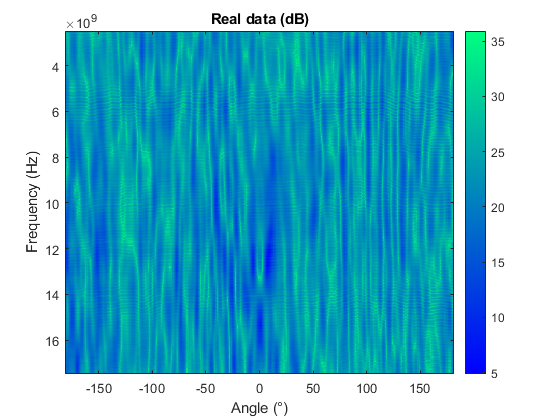

clear
c0 = 3e8;
fmin = 2.5e9; fmax = 17.5e9; % fmin et fmax
th1 = -181; th2=181;  %angle min et max
nth = 362;nf = 400; %Nombre d'échantillons respectivement en angle, et en fréquence.
df = (fmax-fmin)/nf;
dth = (th2-th1)/nth;
freq = fmin:df:fmax-df;
angle = th1:dth:th2;
deltaR = c0/(2*(fmax-fmin));
Wd = c0/(2*df);
Wt = c0/(2*mean(freq)*dth*pi/180);

sigc = 20*log10(abs(chargementHH('drone_hori_av')-chargementHH('vide_hor'))) + 34.5; %Seuil de calibration d'un précédent TP
nf = 400;
sigc = sigc(800:1199,:);
figure
imagesc(angle,freq,20*log10(abs(sigc)));  % Notons bien que là, j'ai mis les angles, puis les fréquences, sciemment.
colormap winter ;colorbar
title('Real data (dB)');xlabel('Angle (°)');ylabel('Frequency (Hz)')

# ISAR

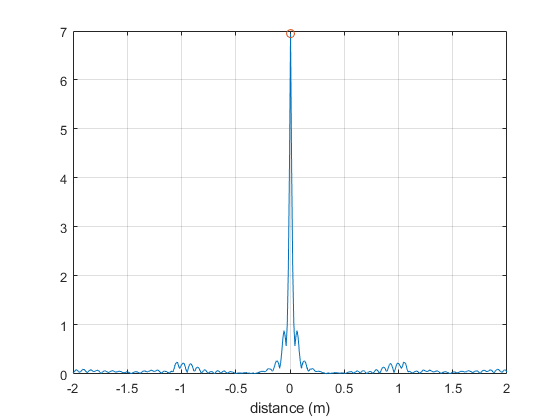

tic
pro_dist=fftshift(ifft(sigc(:,1).*hanning(length(freq))));  %Lorsque la cible est à -180°
distance=linspace(-Wd/2,Wd/2,length(pro_dist)); %
[pics,abscisses] = findpeaks(abs(pro_dist),'MinPeakProminence',2);
figure;plot(distance,abs(pro_dist),'DisplayName','sigc');xlabel('distance (m)');ylabel('');hold on; grid on
scatter(distance(abscisses),pics)

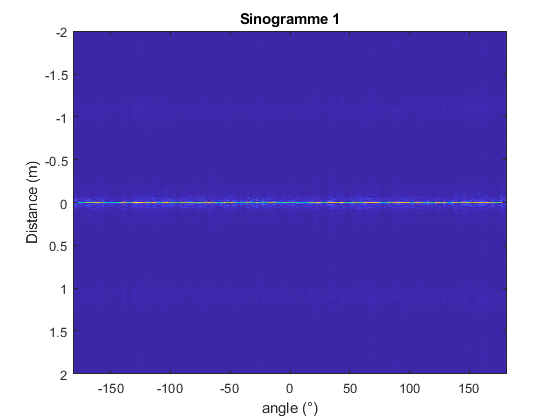

distance=linspace(-Wd/2,Wd/2,length(pro_dist));

sino=fftshift(ifft(sigc),1);
figure;imagesc(angle,distance,abs(sino));xlabel('angle (°)'); ylabel('Distance (m)')
title('Sinogramme 1')

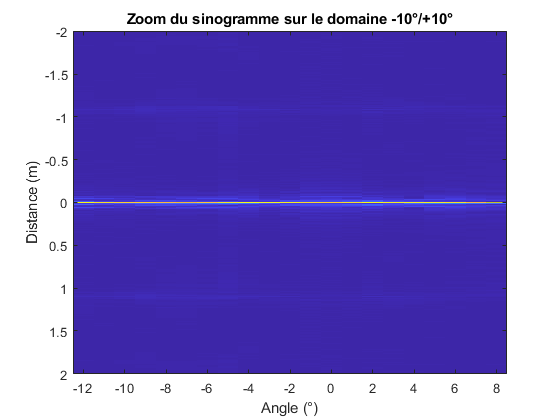

angle_debut = 170;
angle_fin = 190;
indice_debut = floor(angle_debut*nth/362);
indice_fin = floor(angle_fin*nth/362);
angles = indice_debut:indice_fin;
distanceT=linspace(-Wt/2,Wt/2,512);
zoom = sino(:,angles);

figure
imagesc(angle(angles),distance,abs(zoom))
title('Zoom du sinogramme sur le domaine -10°/+10°');xlabel('Angle (°)');ylabel('Distance (m)')

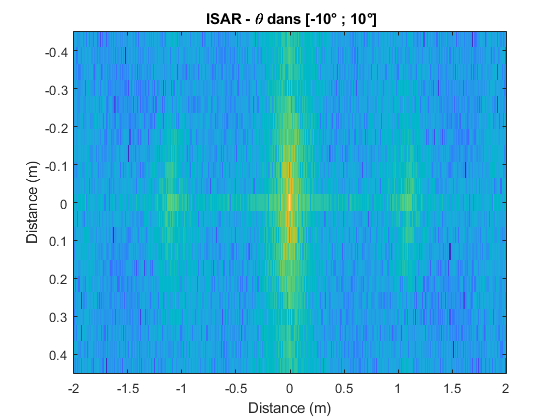

image = fftshift(fft(zoom,[],2),2);
figure
imagesc(distance,distanceT,log10(fliplr((abs(image')))));xlabel('Distance (m)');ylabel('Distance (m)')
title(' ISAR - \theta dans [-10° ; 10°]')
hold on;

## Essai de déconvolution

On peut utiliser une méthode de déconvolution aveugle pour améliorer l'image en sortie d'algorithme.

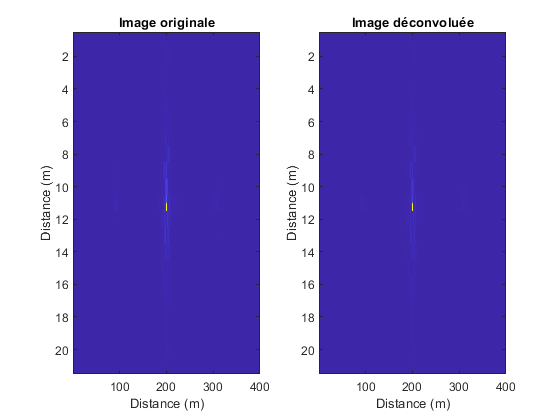

[deconv,psfr] = deconvblind(fliplr(abs(image')),ones(7,7));
figure
% sgtitle('Essai de deconvolution')
subplot(121)
imagesc(fliplr(abs(image')));title('Image originale');xlabel('Distance (m)');ylabel('Distance (m)')
subplot(122)
imagesc(deconv);title('Image déconvoluée');xlabel('Distance (m)');ylabel('Distance (m)')

Nous pouvons améliorer l'image précédente en passant du repère polaire au repère cartésien. En effet, nous souhaitons représenter une image 2D, à partir d'un angle et d'une distance. Il va donc falloir interpoler les données sur une nouvelle grille.

## **Changement de repère**

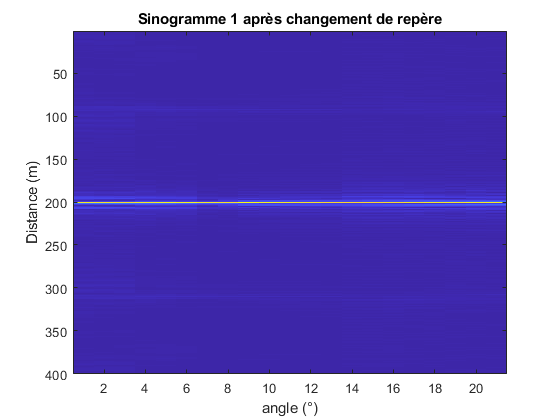

%coord cartesien
distanceT=linspace(-Wt/2,Wt/2,(indice_fin-indice_debut+1));
f1=min(freq);f2=max(freq);
t1=-dth/2;t2=+dth/2;
fx=linspace(f1,f2,length(freq));
fy=linspace(t1,t2,length(distanceT))*pi/180;
[xi,yi]=meshgrid(fx,fy);
%coord polaire
xip=xi.*cos(yi);
yip=xi.*sin(yi);
distanceT=linspace(-Wt/2,Wt/2,(indice_fin-indice_debut+1));
yic=linspace(yip(1,1),yip(length(distanceT),1),length(distanceT));
xifin=sqrt(fx(1,end)^2-yic(1,end)^2);
xic=linspace(f1,xifin,length(freq));
[fx,fy]=meshgrid(xic,yic);
dkx = (fx(1,2)-fx(1,1))*2*pi/c0;  %pas de la grille cartésienne en x
dky = (fy(2,1)-fy(1,1))*2*pi/c0;  %pas de la grille cartésienne en y
Nx = nf;  %Taille de la grille en x
Ny = (indice_fin - indice_debut)+1;  %Taille de la grille en x
N = Nx * Ny;  %Nombre total d'éléments
dx = 1/(Nx*dkx);
dy = 1/(Ny*dky);
tempdata=sigc(:,indice_debut:indice_fin);
datac=griddata(xip.',yip.',tempdata,fx.',fy.','nearest');  %Interpolation
sino3=fftshift(ifft(datac),1);
figure;imagesc(abs(sino3));xlabel('angle (°)'); ylabel('Distance (m)');title('Sinogramme 1 après changement de repère')

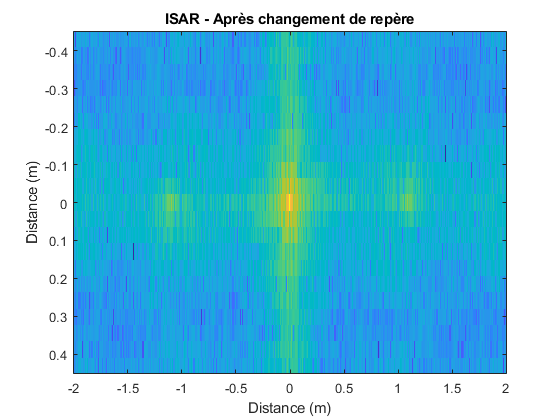

isar2 = fftshift(fft(sino3,[],2),2);
figure;imagesc(distance,distanceT,log10(fliplr(abs(isar2'))));
title('ISAR - Après changement de repère'); xlabel("Distance (m)"); ylabel("Distance (m)")

toc 

Elapsed time is 0.643013 seconds.


## Parcimonie

Nous avons déjà un premier résultat avec l'ISAR. Essayons maintenant d'implémenter SPRITE petit à petit. 

Déjà, SPRITE se voulant parcimonieuse, il faut exprimer notre problème sous la forme suivante : $\sigma$ = **H*****a** + **n**

$\sigma$ correspond aux données de la chambre anéchoïque (il faudra peut-être la flatten) Update 05/02 : En effet il faudra que je flatten.

Dans le document 'SPRITE : A New Sparse Approach for 3D High Resolution RCS Imaging', il est précisé que si l'on a nos données sur une grille cartésienne régulière (ce qui est le cas, avec la variable datac), alors **H **peut s'écrire :

H = $\alpha$ * $sqrt(N)$ * $\delta_\psi$ * $S$ * $F$ * $\delta_\phi$  

Mais, quelles sont les valeurs correspondantes ? update 8/02 ; cf p44 thèse 

Après tout, alpha et N sont juste des coeffs multiplicateurs, ça ne devrait pas non plus tout niquer si c'est égal à 1

S est la matrice de sous-échantillonage.

Construisons les vecteurs et matrices qui nous serons utiles : 

**On vectorise nos données**

tic
flatdata = datac(:);
kx0 = (2*pi*fmin/c0)*sin(angle(indice_debut));
ky0 = (2*pi*fmin/c0)*cos(angle(indice_debut));
kx = kx0*ones(1,Nx);
ky = ky0*ones(1,Ny);
for ind = 1:Nx
    if ind<=Ny
        ky(ind) = ky(ind)+ind*dky;
    end
    kx(ind) = kx(ind)+ind*dkx;
end

**Construction de la matrice de TDF 2D**

Fy = zeros(Ny,Ny);
for i=1:Ny
    for j=1:Ny
        Fy(i,j) = exp(-2*1j*pi*(i-1)*(j-1)/Ny);
    end
end

Fx = zeros(Nx,Nx);
for i=1:Nx
    for j=1:Nx
        Fx(i,j) = exp(-2*1j*pi*(i-1)*(j-1)/Nx);
    end
end
F = kron(Fy,Fx);  %Produit de kronecker

On voit que notre matrice F a la taille correspondant à flatdatac. 

**Le coefficient de déphasage **$\alpha$** à l'origine des grilles du k-space et spatiale : **

alpha = exp(-2*1j*pi*(0*kx0+0*ky0));  %Je considère l'origine comme étant (0,0), pratique. 

**Matrice diagonale de déphasage **$\delta_\phi$** dans le domaine spatial :**

deltaPhix = eye(Nx);
deltaPhiy = eye(Ny);

for ind=0:Nx-1
    deltaPhix(ind+1,ind+1) = exp(-2*1j*pi*kx0*dx*ind);
end

for ind=0:Ny-1
    deltaPhiy(ind+1,ind+1) = exp(-2*1j*pi*ky0*dy*ind);
end
deltaPhi = kron(deltaPhiy,deltaPhix);

**Matrice diagonale de déphasage **$\delta_\psi$** dans le s-space :**

deltaPsi = eye(N); %Là encore, je pars du principe que mon origine est (0,0)

**Matrice S correspondant au sous-échantillonnage**

Il me semble ne pas en avoir besoin, vu que mes données sont déjà regriddées. (cf gridata)

S = (datac(:)-tempdata(:));
S =(S./norm(S))>0;

**Enfin, la matrice H correspondant à notre modèle est : **

**(ATTENTION à la RAM et au temps de calcul si Nx et Ny grands)**

H = alpha*sqrt(N)*deltaPsi*F*deltaPhi;
hermit = conj(H');
toc

Elapsed time is 68.387289 seconds.


Nous avons maintenant un modèle convenable, essayons

## **L1-regularisation**

**La régularisation l1 favorise la parcimonie.**

tic
[al1,status] = l1_ls_nonneg(H/norm(H,2),flatdata,-500,1e-2); %10 marchotte


Solving a problem of size (m=8400, n=8400), with lambda=-5.00000e+02
-----------------------------------------------------------------------------
 iter       gap         primobj         dualobj      step len   pcg iters
   0          Inf    -2.58873e+06            -Inf         Inf        0
   1          Inf    -5.31026e+06            -Inf     3.9e-03        1
   2          Inf    -6.16804e+06            -Inf     9.8e-04        1
   3          Inf    -6.38238e+06            -Inf     2.4e-04        0
   4          Inf    -6.49376e+06            -Inf     1.2e-04        1
   5          Inf    -6.52160e+06            -Inf     3.1e-05        0
   6          Inf    -6.52334e+06            -Inf     1.9e-06        0
   7          Inf    -6.52421e+06            -Inf     9.5e-07        0
   8          Inf    -6.52422e+06            -Inf     1.5e-08        0
   9          Inf    -6.52423e+06            -Inf     7.5e-09        0
  10          Inf    -6.52423e+06            -Inf     3.7e-09       

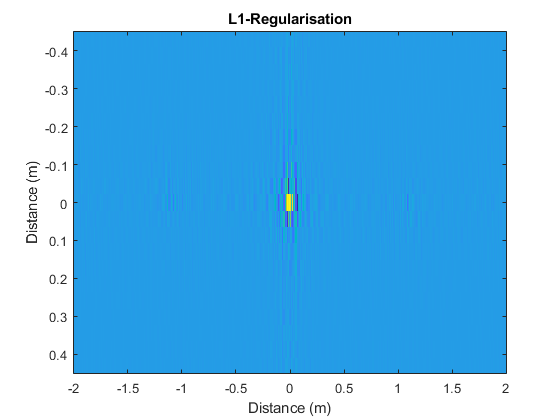

al1 = reshape(al1,Nx,Ny);
figure;
imagesc(distance,distanceT,log10(abs(fliplr(fftshift(al1')))))
title('L1-Regularisation');xlabel('Distance (m)');ylabel('Distance (m)');

toc

Elapsed time is 65.520379 seconds.


## Orthogonal Matching Pursuit

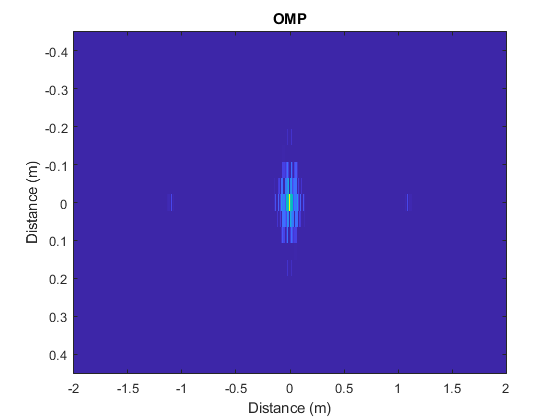

tic
Match = OMP_base(H,flatdata,100);
Match = reshape(Match,Nx,Ny);
figure;
imagesc(distance,distanceT,log10(abs(fliplr(fftshift(Match')))))  %Je repasse au log pour afficher les points brillants, qui ne brillaient pas tant que cela..
title('OMP');xlabel('Distance (m)');ylabel('Distance (m)')

toc

Elapsed time is 7.110392 seconds.


ADMM 

Alors... l'algorithme est expliqué dans le document. Seul 'problème', c'est une plaie à décrypter. Il y a énormément de matrices différentes.

Update 05/02 : En fait la thèse explicite les matrices P, et Dx Dy 

Il doit certainement y avoir des simplifications, étant donné que je laisse une dimension de côté...

**Expression du critère J(a)**

On a besoin de : H, $\mu$ , P, Dx et Dy

tic
P = ones(N,1);
mu = 20;
lambda = 100;
nu = 1;


Dx0 = -1*eye(Nx) + triu(ones(Nx,Nx),1) - triu(ones(Nx,Nx),2);
Dx0(Nx,1) = 1;
Dx = kron(Dx0,eye(Ny));  %Il aurait fallu refaire un produit de kronecker avec INz, mais je suis en 2D.

Dy0 = (-1*eye(Ny) + triu(ones(Ny,Ny),1) - triu(ones(Ny,Ny),2))';
Dy0(1,Ny) = 1;
Dy = kron(eye(Nx),Dy0);

Je remarque tout de même qu'il n'y a pas de Dz en 3D... peut être qu'il n'y a pas de Dy en 2D ? Soit, passons. 

**Algorithme ADMM**

On a ici besoin d'initialiser bon nombres de variables auxiliaires. 

Empiriquement (thèse p109), les paramètres de pénalité $\rho_P$, $\rho_D$, et $\rho_C$ sont satisfaisant avec

%rhoP = Nz/2;  % A vrai dire, si je n'ai pas de z... je ne l'utilise pas :) 
rhoP = 50;
rhoD = 5e2;
rhoC = 5e2;

les vecteurs u et v sont initialisés à 0.

rhoP = 0 implique que les variables vp et up sont.. inexistantes (?) en 2D. 

Dy n'étant pas impliqué non plus, vy et uy disparaissent. 

il nous reste un problème clair et limpide, qu'on peut maintenant résoudre. (ahahahah)

Pour la mise à jour pratique et rapide de a, on a : 

G = hermit*H + rhoD*conj(Dx') + (nu+rhoC+rhoP)*eye(N);
%rank(G) permet de s'assurer de l'inversibilité de cette matrice
invG=eye(N)/G;
dirtyMap = hermit*flatdata;

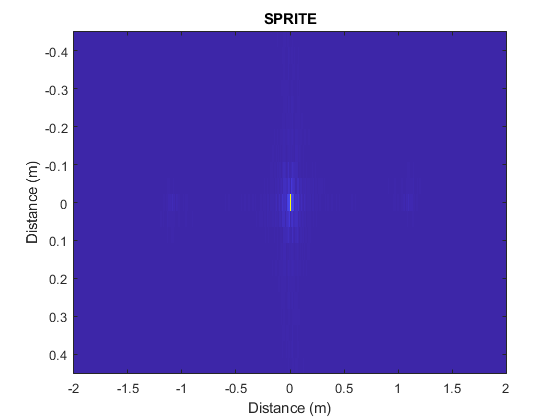

v = [zeros(1,N) ; zeros(1,N) ; zeros(1,N) ; zeros(1,N)];
u = [zeros(1,N) ; zeros(1,N); zeros(1,N) ; zeros(1,N)];% = [up ux uy uc]
clear a 
it = 10;
J = zeros(1,it);
as = zeros(N,it);
ts = zeros(N,it);
ds = zeros(N,it);
evo = zeros(1,it);
residus = zeros(1,it);
for k = 1:it
    t = rhoP*(v(1,:)-u(1,:))' + rhoD*(conj(Dx')*(v(2,:)-u(2,:))'+ conj(Dy')*(v(3,:)-u(3,:))') + rhoC*(v(4,:)-u(4,:))';
    d = (dirtyMap + t); 
    ds(:,k) = d;
    ts(:,k) = t;
    %%%% Mise à jour de la carte %%%%
    a = invG*d;
    as(:,k) = a;
    
    %%%% Mise à jour des variables auxiliaires initiales %%%% 
    v(1,:) = softthresh(a + u(1,:)',mu/rhoP);
    v(2,:) = softthresh(Dx*a+u(2,:)',lambda/rhoD);
    v(3,:) = softthresh(Dy*a+u(3,:)',lambda/rhoD);
    v(4,:) = S .* (a + u(3,:)');


    %%%% Mise à jour des multiplicateurs de Lagrange %%%% 
    u(4,:) = (u(4,:)' +   a - v(4,:)')';
    u(3,:) = (u(3,:)' + Dy*a - v(3,:)')';    
    u(2,:) = (u(2,:)' + Dx*a - v(2,:)')';
    u(1,:) = (u(3,:)' +   a - v(1,:)');
    
    %%%% Critère d'arrêt / convergence / critère à minimiser%%%% 
    %residus(k)= norm(a-v(1,:))+norm(Dx*a - v(2,:)) ;
    J(k) = 0.5*norm(flatdata-H*a)^2 + mu*norm(v(3,:),1) + lambda*norm(v(1,:),1) + nu/2 * norm(a)^2;
end
sprite = reshape(a,Nx,Ny);
figure
imagesc(distance,distanceT,abs(fftshift(sprite')));title('SPRITE');xlabel('Distance (m)');ylabel('Distance (m)')

toc

Elapsed time is 104.723860 seconds.


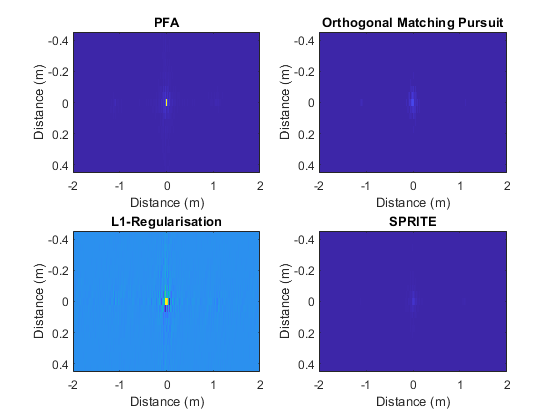

figure
%sgtitle('Comparaison des methodes')
subplot(221)
imagesc(distance,distanceT,(fliplr(abs(isar2'))));title('PFA');xlabel('Distance (m)');ylabel('Distance (m)');

subplot(222)
imagesc(distance,distanceT,(abs(fliplr(fftshift(Match')))));
hold on;
title('Orthogonal Matching Pursuit');xlabel('Distance (m)');ylabel('Distance (m)')

subplot(223)
imagesc(distance,distanceT,(fliplr(abs(fftshift(al1'))))); hold on; title('L1-Regularisation');xlabel('Distance (m)');ylabel('Distance (m)')

subplot(224)
imagesc(distance,distanceT,(abs(fftshift(sprite'))));title('SPRITE');xlabel('Distance (m)');ylabel('Distance (m)');